# Representative Signal Chain

## User parameters

% Camera
p.fl    = 0.5;      %[m] focal length
p.Dapp  = 0.1;      %[m] Apperture Diameter
p.p     = 5e-6;     %[m] pixel pitch
p.cnt   = 2e3;      %[#] sqrt of number of pixels
p.Rate  = [3,50]    %[hz] frame rate of imagery

p = struct with fields:
        fl: 0.5000
      Dapp: 0.1000
         p: 5.0000e-06
       cnt: 2000
      Rate: [3 50]
       int: [0.0500 1.0000e-03]
     bgIrr: 1.0000e-06
       cwl: 6.0000e-07
        bp: 4.0000e-07
    engPhs: 45
      POCA: 5000
      rImg: 30000
    rStart: 840000
      Dtgt: 5
       rfl: 1
      mBuf: 10
    strOSF: 17
    tgtOSF: 3
     bgShp: 0.4000
    maxMag: 13
     lPOCA: [0 7000000 0]


p.int   = [5e-2,1e-3] %[s] integration time

p = struct with fields:
        fl: 0.5000
      Dapp: 0.1000
         p: 5.0000e-06
       cnt: 2000
      Rate: [3 50]
       int: [0.0500 1.0000e-03]
     bgIrr: 1.0000e-06
       cwl: 6.0000e-07
        bp: 4.0000e-07
    engPhs: 45
      POCA: 5000
      rImg: 30000
    rStart: 840000
      Dtgt: 5
       rfl: 1
      mBuf: 10
    strOSF: 17
    tgtOSF: 3
     bgShp: 0.4000
    maxMag: 13
     lPOCA: [0 7000000 0]


p.bgIrr = 1e-6;     %[w/m2/bp] Irradiance on the FP, ideally this would be from a series of simulation 
p.cwl   = 600e-9;   %[m] center wavelength
p.bp    = 400e-9;   %[m] bandpass width
p.bin   = 0

% engagement
p.engPhs= 45;   %[deg] Phase angle between sensor and target velocity vectors
p.POCA  = 5e3;  %[m] Seperation of target and sensor at point of closest approach
p.lPOCA = [0,7000e3,0]%[m] Locating Poca location

p = struct with fields:
        fl: 0.5000
      Dapp: 0.1000
         p: 5.0000e-06
       cnt: 2000
      Rate: [3 50]
       int: [0.0500 1.0000e-03]
     bgIrr: 1.0000e-06
       cwl: 6.0000e-07
        bp: 4.0000e-07
    engPhs: 45
      POCA: 5000
      rImg: 30000
    rStart: 840000
      Dtgt: 5
       rfl: 1
      mBuf: 10
    strOSF: 17
    tgtOSF: 3
     bgShp: 0.4000
    maxMag: 13
     lPOCA: [0 7000000 0]


p.rImg  = 30e3; %[s] range which we switch integration 
p.rStart= 840e3;%[m] range from Poca we start the engagement
p.Dtgt  = 5;    %[m] Diameter of target
p.rfl   = 1;    %[ratio] reflectance   

% Simulation Params
p.mBuf  = 10;   %[pixels] How much motion we'll allow
p.strOSF= 17;   %[scl] determines how much we'll oversample the psf for the stars
p.tgtOSF= 3;    %[tgt] determines how much we'll over sample the target
p.bgShp = .4;   %[] drives how quickly the SL falls off >1 quicker, <1 slower, 1 = radially
p.maxMag= 13;    %[] drives max mag of those stars (3x drop in stars/mag)

%constants
p.mV_sun = -26.74

%some place holders
d.sig = zeros(p.cnt/p.bin)

## Read in data and create LUTs

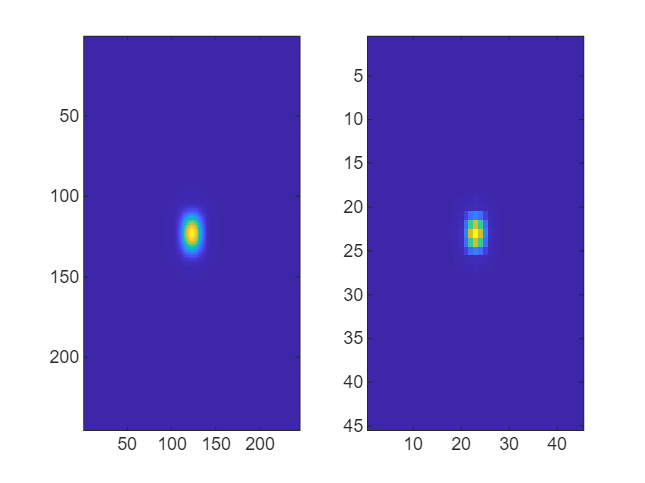

%Make representative SL Im (Ideally this comes from somewhere else, like a
%SL LUT dependant on sun and earth angles + zodiacal)
[x,y]   = meshgrid(linspace(-1,1,p.cnt),linspace(-1,1,p.cnt));
r       = 1-sqrt(x.^2+y.^2); r = r-min(r(:));;
s.bg    = p.bgIrr*abs(r/max(r(:)).^p.bgShp);
if 0; imagesc(abs(r.^p.bgShp)); end; %for testing

% Generate a PRP for our stars (Note: for a system with a changing Focus to
% keep up with the target, this would be an LUT)
[psf, x, y] = diffraction_psf(p.p/p.strOSF, p.fl/p.Dapp,p.cwl); % get diffraction psf for CWL
prp0 = conv2(psf,ones(p.strOSF),'same'); %turn it into a prp
s.strPRP = padarray(prp0,[1 1]*round(p.mBuf *p.strOSF/2),0,'both'); %pad array for motion

%Do the same thing for our target. (Note: This should be an LUT based on
%the focus of the system and the range of the target)
[psf, x, y] = diffraction_psf(p.p/p.tgtOSF, p.fl/p.Dapp,p.cwl); % get diffraction psf for CWL
prp0 = conv2(psf,ones(p.tgtOSF),'same'); %turn it into a prp
s.tgtPRP = padarray(prp0,[1 1]*round(p.mBuf *p.tgtOSF/2),0,'both'); %pad array for motion
if 1; subplot(1,2,1);imagesc(s.strPRP);subplot(1,2,2);imagesc(s.tgtPRP); end;


%Generate a star LUT
fov = p.p*p.cnt/p.fl*180/pi

fov = 1.1459

s.starLUT = star_lut(p.maxMag,1,fov); %This will just give a rough

res = 0.0100

samples =    13.0000   12.9900   12.9800   12.9700   12.9600   12.9500   12.9400   12.9300   12.9200   12.9100   12.9000   12.8900   12.8800   12.8700   12.8600   12.8500   12.8400   12.8300   12.8200   12.8100   12.8000   12.7900   12.7800   12.7700   12.7600   12.7500   12.7400   12.7300   12.7200   12.7100   12.7000   12.6900   12.6800   12.6700   12.6600   12.6500   12.6400   12.6300   12.6200   12.6100   12.6000   12.5900   12.5800   12.5700   12.5600   12.5500   12.5400   12.5300   12.5200   12.5100


fovScl = 2.0264e-05


%get sun irrad
dat = readtable('SolarSpec.txt');
wl = dat.Wavelength_nm_*1e-9;
idx = find((wl>(p.cwl-p.bp/2))==(wl<(p.cwl+p.bp/2)));
s.sun = trapz(dat.Wavelength_nm_(idx),dat.Extraterrestrial_W_m2_nm_(idx));
clearvars -except p s;

## Generate engagements

vSens   = [-7e3,0,0]
vTgt    = [cosd(p.engPhs),0,sind(p.engPhs)]*-7e3

%% This will take a background image and embedd stars using the PRPLUT
if nargin<2 % If you do not give it a boresight quaternion, it'll use the obs2tgt quaternion
    qGcrf2Opt = p.qGcrf2Sens;
end
p.qGcrf2Opt = qGcrf2Opt;
ra  = p.raDec(1);
dec = p.raDec(2);
fov = p.fov;
% Determine raDec Bounds, giving it a little buffer
buf = sqrt(sum(fov.^2));
raBnd1 = ra+[-1,1]*buf;
decBnd = dec+[-1,1]*buf;
% If RA bounds roll over at all, create another bound which we'll check. 
if raBnd1(1)<-pi 
    raBnd2=[raBnd1(1)+2*pi,pi];
elseif raBnd1(2)>pi
    raBnd2=[-pi,raBnd1(2)-2*pi];
else
    raBnd2=raBnd1;
end
% make sure decBnd not > then 85deg
if sum(abs(decBnd)>1.4835299)
    warning('Declination Bounds >85deg')
end
%%%%%% create library of stars that are near the FOV
idx = find((((p.starCatLUT(:,1)>raBnd1(1)) & (p.starCatLUT(:,1)<raBnd1(2))) |...
    ((p.starCatLUT(:,1)>raBnd2(1)) & (p.starCatLUT(:,1)<raBnd2(2)))) &...
    ((p.starCatLUT(:,2)>decBnd(1)) & (p.starCatLUT(:,2)<decBnd(2))));
stars = p.starCatLUT(idx,:);
% Create unit vector for stars so that we can rotate this vector
% from reported J2000 GCRS frame to the instantaneous MOD frame
starV0 = [cos(stars(:,1)).*cos(stars(:,2)) ...
    sin(stars(:,1)).*cos(stars(:,2)) ...
     sin(stars(:,2))];

%%%%%% Add in Newtonian Stellar Aberration (speed of light)
% phat = (phat + v/c) / |phat + v/c|
% Get barycentric velocity of Earth
vEarth = baryvel(p.tframeDNum(p.frame));
% sensor velocity
v = vEarth+p.sensP(4:6);
% Add in velocity
starV = starV0 + v/p.cLight;
% re-normalize
starV= starV./...
    repmat(sqrt(sum(starV.^2,2)),1,3);
%%%%%%% rotate stars to optical frame and turn into pixel coords
starsp = quatrotate(qGcrf2Opt, starV);
x = starsp(:,2)./starsp(:,1); % [rad,p] Yp becomes FP_X "left"
y = starsp(:,3)./starsp(:,1); % [rad,p] Zp becomes FP_Y "up"
%get in units of FOVs, then scale to pixels
px = (-y/fov(1)+0.5)*p.cnt(1)/p.bin-0.5;
py = (-x/fov(2)+0.5)*p.cnt(2)/p.bin-0.5;
%%%%%%% get motion vector by looking at raDec pointing
% frame and this frame. 
di = 0; % These become a vector of points to sample the motion. 
dj = 0;
if (p.motionSam>1)                
    % get the RaDec looking point
    pt =   [cos(ra).*cos(dec) ...
            sin(ra).*cos(dec) ...
             sin(dec)];         
    %rotate current looking point by last quaternion             
    starsp0 = quatrotate(p.qOptLast, pt); % look at our current quat rotated to our center point
    x0 = starsp0(:,2)./starsp0(:,1); % [rad] Yp becomes FP_X "left"
    y0 = starsp0(:,3)./starsp0(:,1); % [rad] Zp becomes FP_Y "up"
    %get in units of FOVs, then scale to pixels
    px0 = (-y0/fov(1)+0.5)*p.cnt/p.bin-0.5;
    py0 = (-x0/fov(2)+0.5)*p.cnt/p.bin-0.5;
    
    % get difference in location in pixels 
    if p.frame == 1
        dt = p.int/(p.times(p.frame+1)-p.time);
    else
        dt = p.int/(p.time-p.times(p.frame-1));
    end
    dx = (p.cnt/2 - px0)*dt;
    dy = (p.cnt/2 - py0)*dt;
    di = round(p.prpOSF*p.bin*linspace(-dx/2,dx/2,p.motionSam));
    dj = round(p.prpOSF*p.bin*linspace(-dy/2,dy/2,p.motionSam));
    blur = sum([dx,dy].^2)^.5;
end   

% get only the stars contained within FOV. 
f = (px > 0) & (py > 0) & (px<(p.cnt/p.bin)) & (py<(p.cnt/p.bin));
px = px(f);
py = py(f);
mv = stars(f,3);            
% turn into irradiance and then electrons
irrApp = p.sun*10.^(-(mv-p.mV_sun)/2.5);
elec   = irrApp.*p.cwl/p.hPlank/p.cLight*p.int.*pi*(p.dApp^2-p.dObs^2)/4; 
% get pixel locations    
I = round(px);
J = round(py);
% and phasing for PRP
i = round(p.prpOSF*(px-I));
j = round(p.prpOSF*(py-J));

%initialize sig
p.SIG = p.base; 
%indicies to add add to index of base image
idI = p.PRPstarLUT.idxIm(:,1); 
idJ = p.PRPstarLUT.idxIm(:,2);
%indicies to add to subsample
idi = p.PRPstarLUT.idx{p.binIdx}(:,1);
idj = p.PRPstarLUT.idx{p.binIdx}(:,2);
%indicies for sampling prp incase the indices exceed dims of
%image
prpi = idI-min(idI)+1;
prpj = idJ-min(idJ)+1;
% For each star get the background and sample the PRP and add
% them together in the right place in the SIG
SZ = p.cnt/p.bin;
for str = 1:length(elec); 
    prp = p.PRPstarLUT.data{p.focusIdx,p.binIdx}(idi+i(str),idj+j(str));
    if p.motionSam>1
        sz = size(p.PRPstarLUT.data{p.focusIdx,p.binIdx});
        for ii = 1:length(idi)
            for jj = 1:length(idj)
                iii = idi(ii)+i(str)+di; iii(iii<1) = 1; iii(iii>sz(1)) = sz(1);
                jjj = idj(jj)+j(str)+dj; jjj(jjj<1) = 1; jjj(jjj>sz(2)) = sz(2);
                prp(ii,jj) = mean(p.PRPstarLUT.data{p.focusIdx,p.binIdx}(iii,jjj),'all');
            end
        end
    end
    %get rid of pixels that go beyond boarders of image;
    II = idI+I(str); JJ = idJ+J(str); 
    prpi = idI-min(idI)+1; prpj = idJ-min(idJ)+1;
    ind = find((II>SZ(1))+(II<1)+(JJ>SZ(2))+(JJ<1));
    II(ind) = []; JJ(ind) = [];
    prpi(ind) = []; prpj(ind) = [];
    bg = double(p.baseSig(II,JJ));
    star = prp(prpi,prpj).*p.qetxLUT.data{p.binIdx}(II,JJ)*elec(str);
    p.SIG(II,JJ)=uint16(p.NoiseFun(bg+star)/p.QSE+p.dcFloor*p.bin^2);
end 







## Functions

% Generate a psf
function [psf, x, y] = diffraction_psf(pixel_pitch, f_number, wavelength)
    % Generates the diffraction-limited point spread function (PSF).
    
    % Input arguments:
    %   pixel_pitch: Pixel pitch in meters.
    %   f_number: f-number of the optical system.
    %   wavelength (optional): Wavelength of light in meters. Defaults to 550nm.
    
    % Output arguments:
    %   psf: The PSF array.
    %   x: The x-coordinates of the PSF grid.
    %   y: The y-coordinates of the PSF grid.
    
    if nargin < 3
        wavelength = 550e-9; % Default wavelength: green light
    end
    
    % Calculate the Airy disk radius (first minimum)
    airy_radius = 1.22 * wavelength * f_number;
    
    % Create a grid for the PSF
    psf_size = ceil(6 * airy_radius / pixel_pitch); % Size of the PSF array
    if mod(psf_size, 2) == 0  % Ensure psf_size is odd for centering
        psf_size = psf_size + 1;
    end
    
    x = linspace(-psf_size/2, psf_size/2, psf_size) * pixel_pitch;
    y = linspace(-psf_size/2, psf_size/2, psf_size) * pixel_pitch;
    [X, Y] = meshgrid(x, y);
    r = sqrt(X.^2 + Y.^2);
    
    % Calculate the PSF using the Airy disk formula
    psf = zeros(size(r));
    nonzero_r = r > 0;
    psf(nonzero_r) = (2 * besselj(1, pi * r(nonzero_r) / airy_radius) ./ (pi * r(nonzero_r) / airy_radius)).^2;
    psf(r == 0) = 1.0; % Central maximum
    
    % Normalize the PSF (integral should be 1)
    psf = psf / sum(psf(:));
end

function starLUT = star_lut(mag,scl,FoV)
% This will just generate a random distribution of stars. For magnitudes,
% it uses the rough approximation that every order of magnitude yields a
% factor of 3 increase in the number of stars to create a PDF. 

% Input arguments:
%   mag: limits the maximum magnitude of stars
%   count: number of stars in total
%   FoV: size of the field of view, used to limit number of stars

% Output arguments:
%   a mock star catalog

%set up sampling
res     = 0.01
samples = mag-[0:res:mag]
%create a pdf using the approximation that every magnitude there are about
%3x as many stars
magPDF = 3.^((mag-[0:.01:mag]));
fovScl = FoV^2/(360*180) % a scale factor based on the average number of stars in a FoV
num_samples = round(sum(magPDF*res)*scl*fovScl);

%get number or magnitude quantizations
n_categories = length(magPDF);

% Create the cumulative distribution function (CDF).
cdf = cumsum(magPDF)/sum(magPDF);

% Generate uniform random numbers between 0 and 1.
random_numbers = rand(num_samples, 1);

% Initialize the output vector.
starLUT = zeros(num_samples, 3);

% Use CDF to distribute magnitudes appropriately
for i = 1:n_categories
  starLUT((random_numbers <= cdf(i)) == (starLUT(:,1)==0),1) = samples(i);  
end

starLUT(:,2) = rand(num_samples,1)*2048;
starLUT(:,3) = rand(num_samples,1)*2048;

end
